clearvars
load lombardgrid_paired/corpusCleaned.mat

[~, fs] = audioread(fullfile('lombardgrid_paired/audio/',...
                [corpusCleaned.FNAME_P{1}, '.wav']));

frameSize = fix(0.02 * fs);
win = hann(frameSize,"periodic");
overlap = 0.50;
shiftSize = fix((1 - overlap) * frameSize);

%%  Assume that each utterances has sounds less than 20 
size = [height(corpusCleaned) * 500*2 6];

utterance_info = table('Size', size, 'VariableTypes', {'string','int32','double','double','double','double'}, ...
             'VariableNames', {'utterance','frame','intensity','tilt','intensity_norm','tilt_norm'});

tic

endIdx = 0;

for i = 1:height(corpusCleaned)

    if ~mod(i,100), disp(i), end

    startIdx = endIdx + 1;

    [audio_p, fs] = audioread(fullfile('lombardgrid_paired/audio/',...
              [corpusCleaned.FNAME_P{i}, '.wav']));
    [audio_l, ~] = audioread(fullfile('lombardgrid_paired/audio/',...
              [corpusCleaned.FNAME_L{i}, '.wav']));

    [tilt_p, int_p, size_p] = getIntensityTilt(audio_p, fs, frameSize, win, overlap);
    [tilt_l, int_l, size_l] = getIntensityTilt(audio_l, fs, frameSize, win, overlap);

    endIdx = startIdx + size_p - 1;
    
    utterance_info.utterance(startIdx : endIdx) = corpusCleaned.FNAME_P{i};
    utterance_info.frame(startIdx : endIdx) = 1:size_p;
    utterance_info.intensity(startIdx : endIdx) = int_p;
    utterance_info.tilt(startIdx : endIdx) = tilt_p;
    utterance_info.intensity_norm(startIdx : endIdx) = normalize(int_p,'range');
    utterance_info.tilt_norm(startIdx : endIdx) = normalize(tilt_p, 'range');
    

    startIdx = endIdx + 1;
    endIdx = startIdx + size_l - 1;

    utterance_info.utterance(startIdx : endIdx) = corpusCleaned.FNAME_L{i};
    utterance_info.frame(startIdx : endIdx) = 1:size_l;
    utterance_info.intensity(startIdx : endIdx) = int_l;
    utterance_info.tilt(startIdx : endIdx) = tilt_l;
    utterance_info.intensity_norm(startIdx : endIdx) = normalize(int_l, 'range');
    utterance_info.tilt_norm(startIdx : endIdx) = normalize(tilt_l, 'range');
    
end

toc

utterance_info = rmmissing(utterance_info);

save('utterance_tilt_intensity_start',"utterance_info");
% save('utterance_tilt_intensity',"utterance_info");
%%

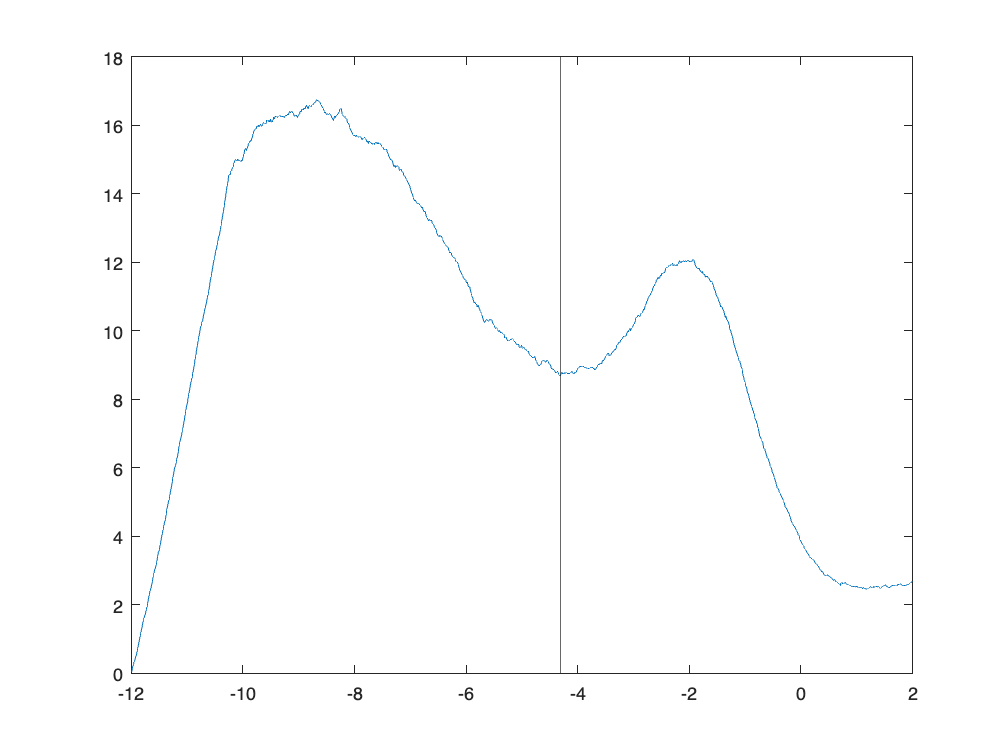

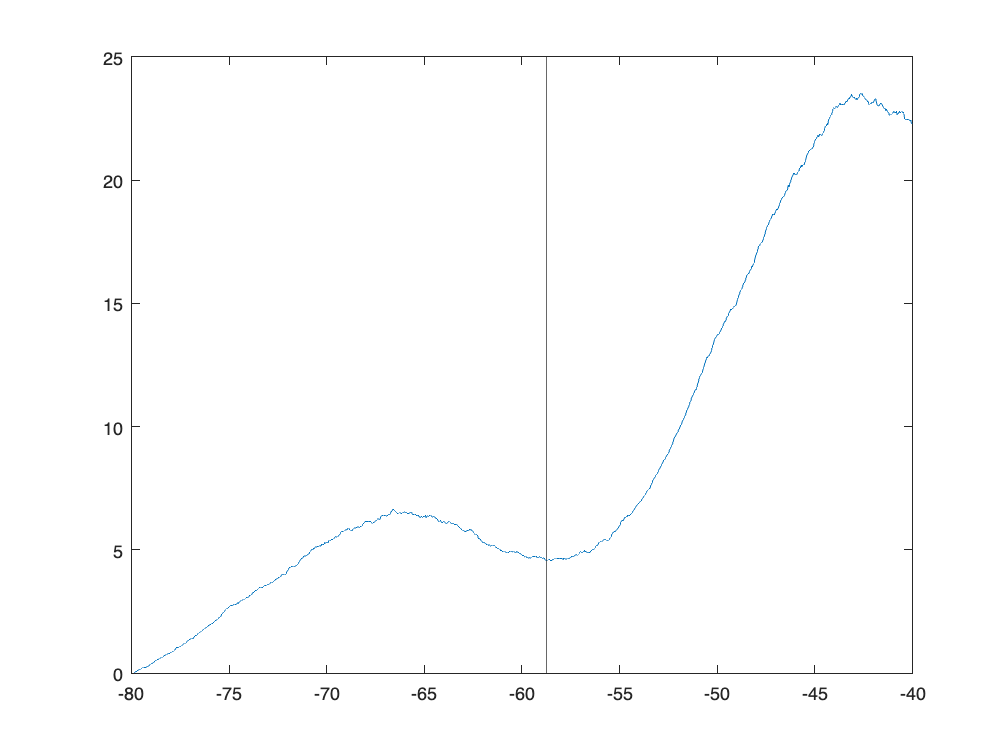

clearvars;
load lombardgrid_paired/corpusCleaned.mat
% load utterance_tilt_intensity.mat
load utterance_tilt_intensity.mat

tilt_threshold = zeros(55,1);
intensity_threshold = zeros(55,1);

targetTilt = -6;
targetIntensity = -60;

for i = 2:55
    
    spkr = utterance_info(contains(utterance_info.utterance, sprintf('s%d_p',i)),:);
    
    % spkr.tilt_norm = mean(spkr.tilt_norm) - spkr.tilt_norm;
    
    % scatter(spkr,"frame","intensity");
    % xline(18,'LineWidth',4,'Color','r')
    % scatter(spkr,"frame","tilt");
    % xline(18,'LineWidth',4,'Color','r')
    % 
    % scatter(spkr,"tilt_norm","intensity_norm")
    
    % a = [1 -0.97];
    % b = 1;
    intensity = spkr.intensity(-80 < spkr.intensity & spkr.intensity < -40);
    tilt = spkr.tilt(-12 < spkr.tilt & spkr.tilt < 2);

    fs = 1024;
    
    windowSize = fs /8; 
    b = (1 / windowSize) * ones(1, windowSize);
    a = 1;
    
    [value, bins] = histcounts(tilt,fs);
    bins = (bins(1:end-1) + bins(2:end)) / 2;
    value = filter(b, a, value);
    % value = h1.Values;
    [~,locs] = findpeaks(-value,"MinPeakDistance",fs/3.5);

    [~, Idx] = min(abs(bins(locs) - targetTilt));

    tilt_threshold(i) = bins(Idx);


    figure;
    plot(bins,value)
    hold on
    xline(bins(locs(Idx)))
    hold off


    [value, bins] = histcounts(intensity,fs);
    bins = (bins(1:end-1) + bins(2:end)) / 2;
    value = filter(b, a, value);
    [~,locs] = findpeaks(-value,"MinPeakDistance",fs/3.5);

    [~, Idx] = min(abs(bins(locs) - targetIntensity));

    intensity_threshold(i) = bins(Idx);

    figure;
    plot(bins,value)
    hold on
    xline(bins(locs(Idx)))
    hold off

end


tilt_threshold

tilt_threshold =          0
   -8.6797
   -5.5391
   -6.1406
   -6.0625
   -5.7812
   -5.6016
   -5.6875
   -5.5391
   -7.3984


intensity_threshold

intensity_threshold =          0
  -22.3984
   -8.1641
  -10.2500
   -6.8672
  -16.7734
  -16.1797
  -17.2500
  -14.4609
   -9.3125


function [spectilt, intensity, n] = getIntensityTilt(audio, fs, frameSize, win, overlap)
    
        method = 6;
        shiftSize = fix((1 - overlap) * frameSize);
%         
%         n = fix((length(audio) - (frameSize -  shiftSize)) / shiftSize) - 1;
%         n = fix(n/3);
        n = fix((0.4*fs - (frameSize -  shiftSize)) / shiftSize) - 1;

        startIdx = 1;
        endIdx = startIdx + frameSize - 1;
        
        spectilt = zeros(n,1);
        intensity = zeros(n,1);
        
        for i = 1:n
        
            audioFrame = audio(startIdx : endIdx) .* win;
            audioFrame = audioFrame - mean(audioFrame);
        
            spectilt(i) = myGetSpectralTilt(audioFrame, fs, method);
            intensity(i) = mag2db(rms(audioFrame));
        
            startIdx = startIdx + shiftSize;
            endIdx = startIdx + frameSize - 1;
        
        end
end